# Two Heaters: Dynamic Temperature Modeling

**Objective**: Derive a nonlinear transient model for two heaters and compare the model predictions with the Arduino temperature control lab measurements. The temperature control lab has two transistor heaters and two temperature sensors as shown in the figure below.

## Lectures - Choose one of the following lectures

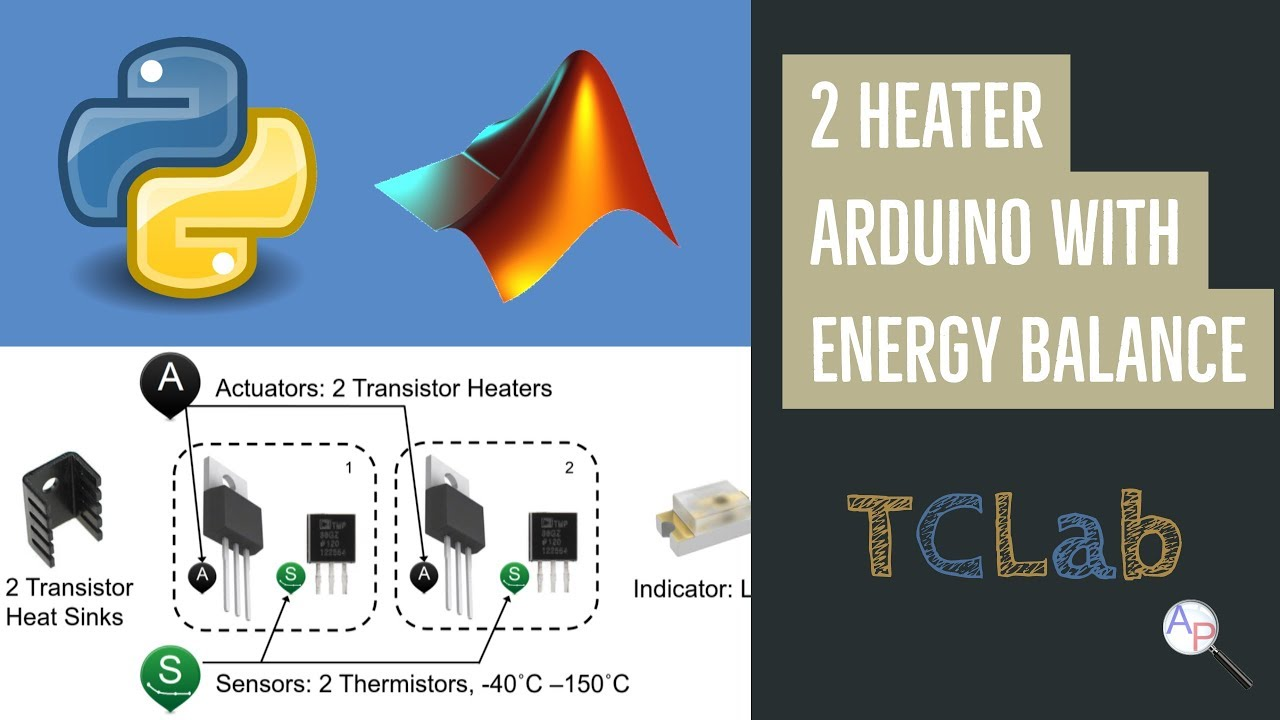

### [View Lecture](https://www.youtube.com/watch?v=SWiLkVJCdfA)

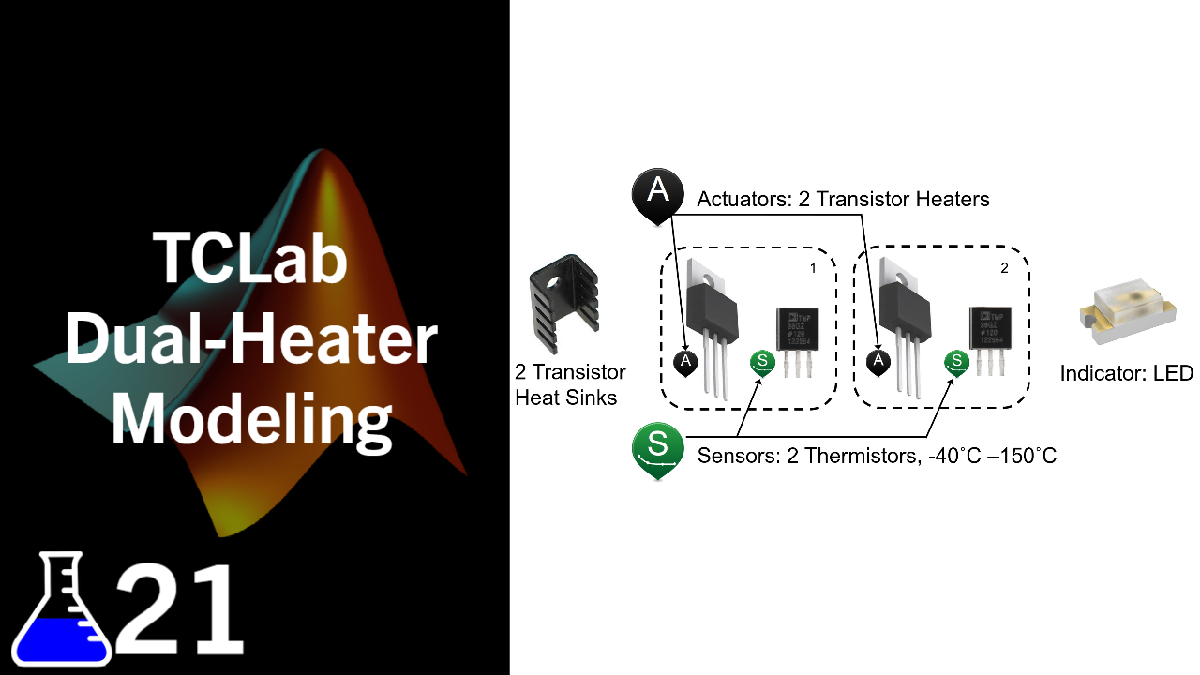

### [View Lecture](https://youtu.be/XUty82ElK5w)

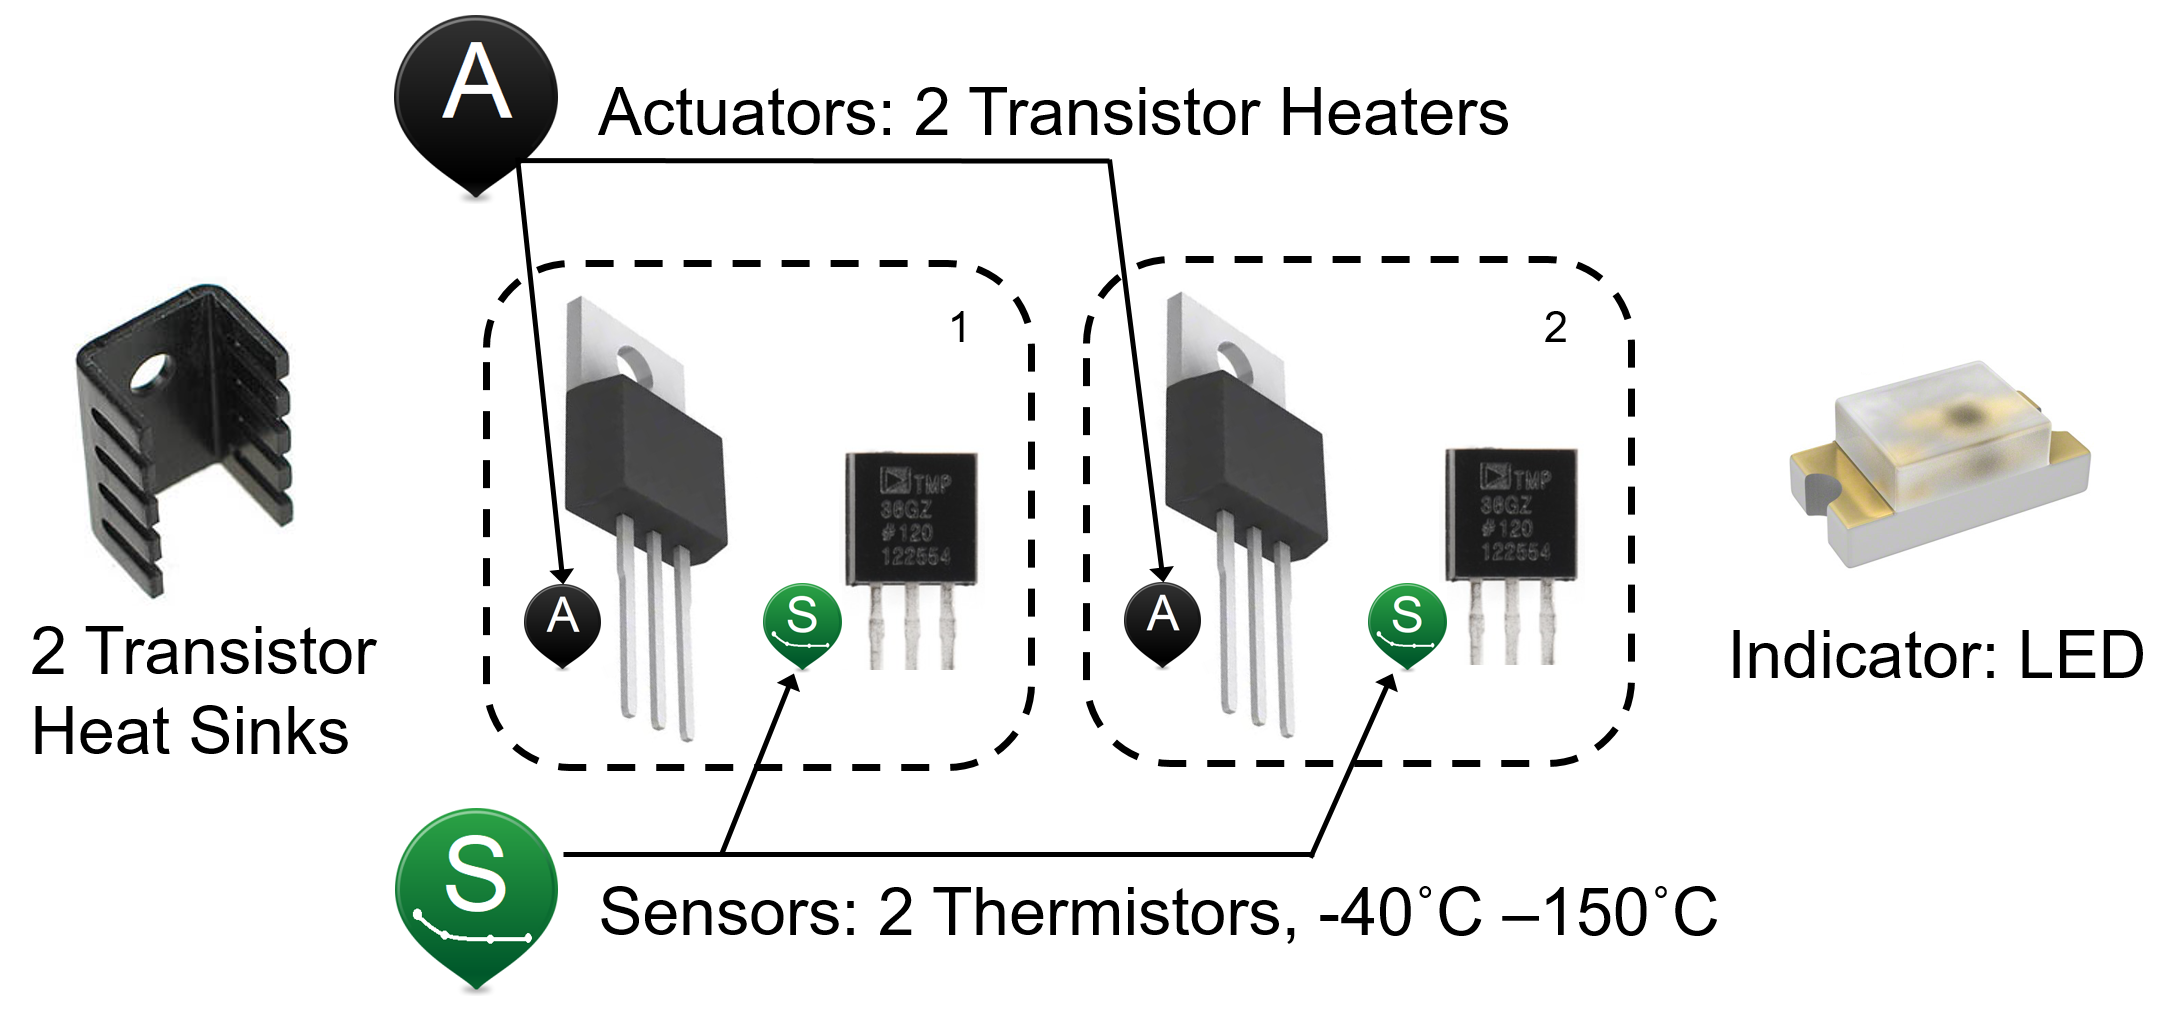

The model for the dual heater system is similar to the single heater model except that the surface is further differentiated for area that is between the two heaters (2 $\text{cm}^2$) and the area that is not coupled between the heaters (10 $\text{cm}^2$). Also, heater 2 dissipates a maximum of 0.75 W while heater 1 dissipates a maximum of 1.0 W.


$$\matrix{

\textbf{Component} & \textbf{Value}\cr
\text{Initial Temperature}(T_0) & 293.15 \text{ K }(20^\circ\text{C})\cr
\text{Ambient Temperature}(T_\infty)& 293.15 \text{ K }(20^\circ\text{C})\cr
\text{Heater 1 Output}(Q_1) & 0-100\%\cr
\text{Heater 1 Factor}(\alpha_1) & 0.0123 \text{ W/(\% heater)}\cr
\text{Heater 2 Output}(Q_2) & 0-100\%\cr
\text{Heater 2 Factor}(\alpha_2) & 0.0062 \text{ W/(\% heater)}\cr
\text{Heat Capacity}(C_p) & 500 \text{ J/kg-K}\cr
\text{Surface Area Not Between Heaters}(A) & 1.0*10^{-3}\text{ m}^2(10\text{ cm})\cr
\text{Surface Area Between Heaters}(A_s) & 2.0*10^{-4}\text{ m}^2(2\text{ cm})\cr
\text{Mass}(m) & 0.004\text{ kg }(4 \text{ gm })\cr
\text{Conduction Time Constant}(\tau) & 20.3 \text{ sec}\cr
\text{Overall Heat Transfer Coefficient} (U) & 4.7 \text{ W/m}^2\text{-K}\cr
\text{Overall Heat Transfer Coefficient Between Heaters}(U_s) & 15.45 \text{ W/m}^2\text{-K}\cr
\text{Emissivity}(\epsilon) & 0.9\cr
\text{Stefan Boltzmann Constant }(\sigma) & 5.67*10^{-8} \text{ W/m}^2\text{-K}^4\cr
}$$


Create a dynamic model of the dynamic response between the input power to each transistor and the temperature sensed by each thermistor. The model is similar to the energy balance model for a single heater but now includes convective and radiative heat transfer between the two heating elements.


$$Q_{C12} = U \, A_s \, \left(T_2-T_1\right)$$



$$Q_{R12} = \epsilon\,\sigma\,A\,\left(T_2^4-T_1^4\right)$$


Two energy balance equations describe the dynamic temperature response of the two temperature sensors given the heater inputs.


$$m\,c_p\frac{dT_1}{dt} = U\,A\,\left(T_\infty-T_1\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T_1^4\right) + Q_{C12} + Q_{R12} + \alpha_1 Q_1$$



$$m\,c_p\frac{dT_2}{dt} = U\,A\,\left(T_\infty-T_2\right) + \epsilon\,\sigma\,A\,\left(T_\infty^4-T_2^4\right) - Q_{C12} - Q_{R12} + \alpha_2 Q_2$$


Use these equations to develop a dynamic simulation of the temperature response due to an impulse (off, on, off) in the heater outputs. Leave the heater on for sufficient time to observe nearly steady state conditions.

## Dual Heater Model

Investigate issues such as whether radiative heat transfer is significant, is the temperature response inherently first order or higher order, and what values of uncertain parameters in the physics based model help the predicted temperature agree with the data.

## **Dual Heater Model + Arduino**

Test the agreement of the model with the Arduino temperature control lab. Report the cumulative error and the average error over 10 minutes with a step test for heater 1 at 10 seconds and heater 2 at 5 minutes.

### MATLAB

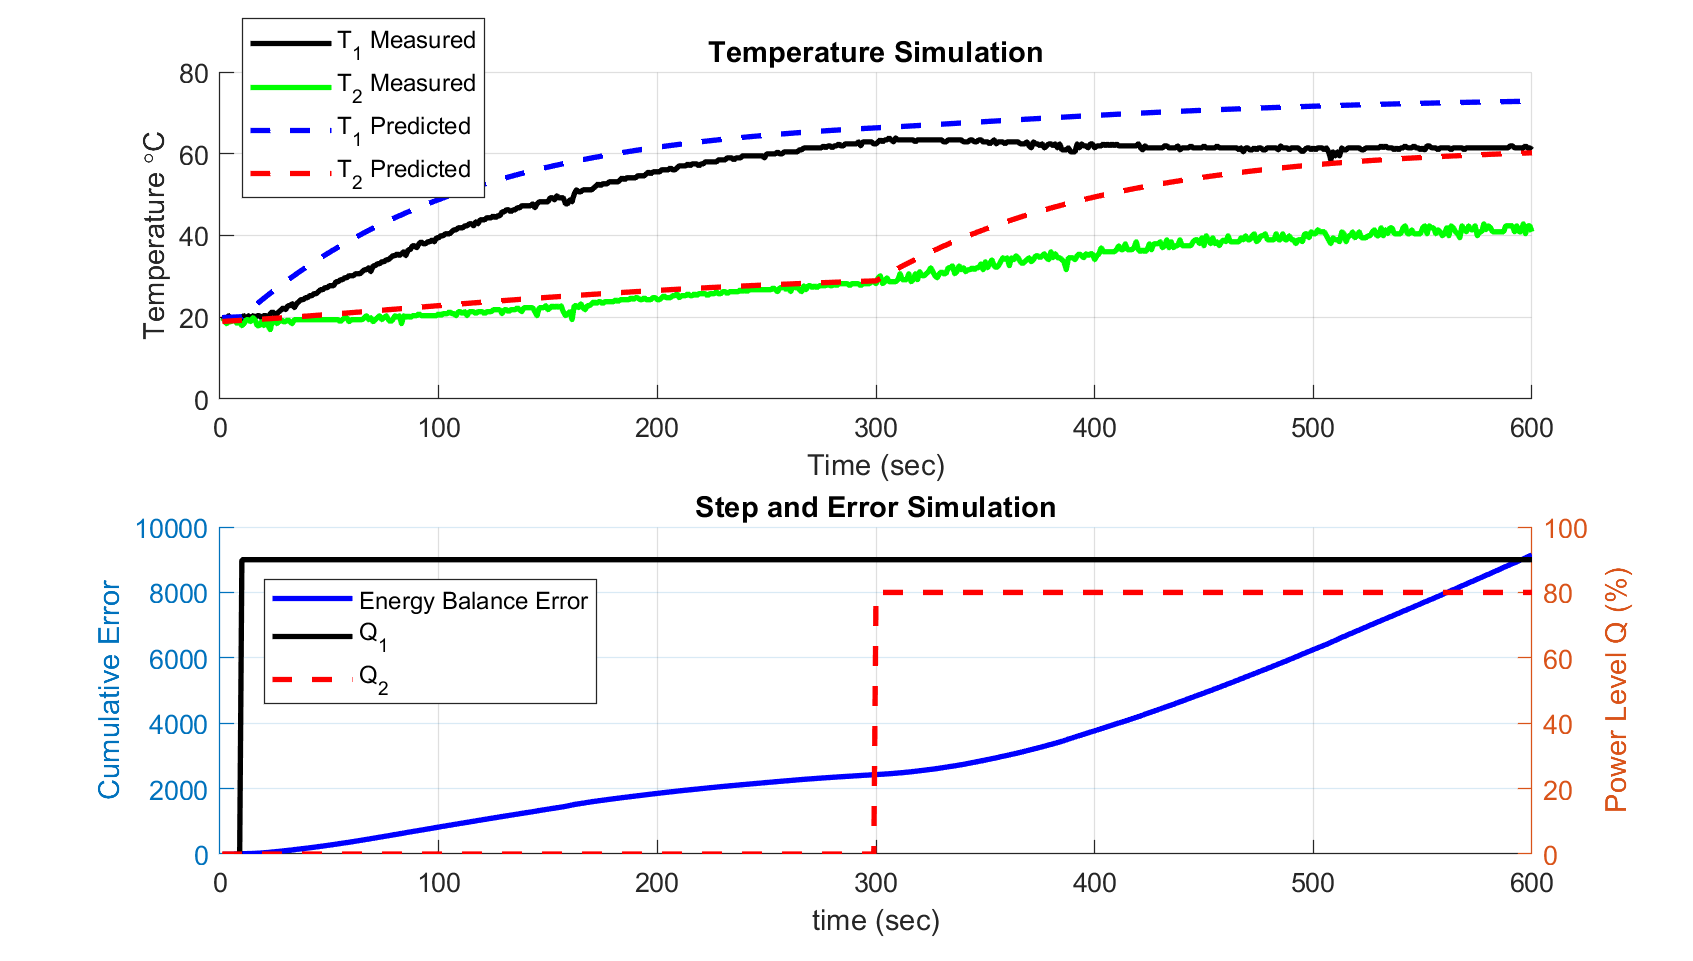

  [**Download MATLAB TCLab Files for Dual Heaters**](https://apmonitor.com/pdc/uploads/Main/tclab_matlab_mimo.zip)

### Simulink

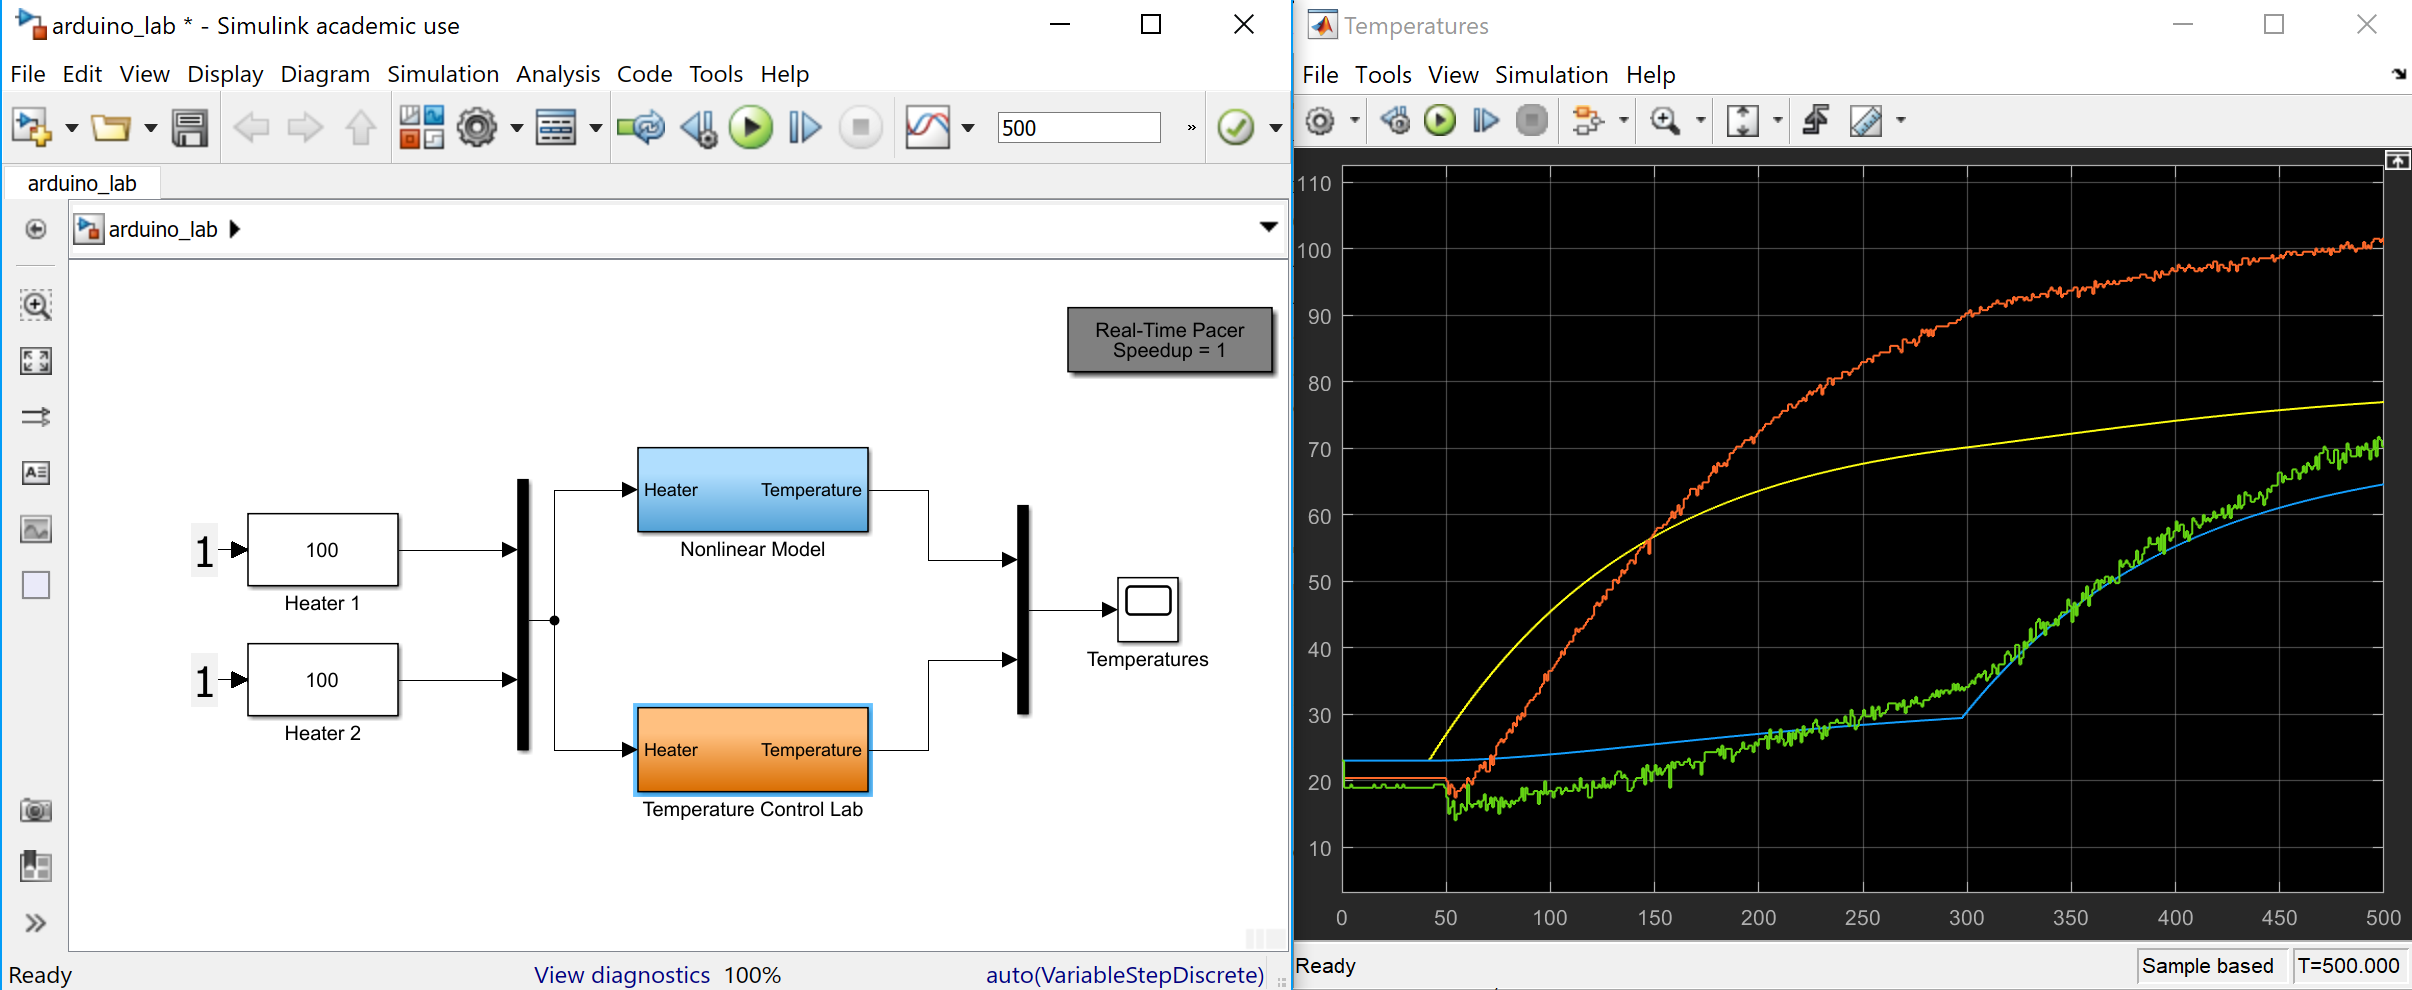

 [**Download Simulink TCLab Files for Dual Heaters**](https://apmonitor.com/pdc/uploads/Main/tclab_simulink_mimo.zip)

function dTdt = heat2(~,x,Q1,Q2)
    % Parameters
    Ta = 23 + 273.15;   % K
    U = 10.0;           % W/m^2-K
    m = 4.0/1000.0;     % kg
    Cp = 0.5 * 1000.0;  % J/kg-K    
    A = 10.0 / 100.0^2; % Area in m^2
    As = 2.0 / 100.0^2; % Area in m^2
    alpha1 = 0.0100;    % W / % heater 1
    alpha2 = 0.0075;    % W / % heater 2
    eps = 0.9;          % Emissivity
    sigma = 5.67e-8;    % Stefan-Boltzman

    % Temperature States
    T1 = x(1);
    T2 = x(2);

    % Heat Transfer Exchange Between 1 and 2
    conv12 = U*As*(T2-T1);
    rad12  = eps*sigma*As * (T2^4 - T1^4);

    % Nonlinear Energy Balances
    dT1dt = (1.0/(m*Cp))*(U*A*(Ta-T1) ...
            + eps * sigma * A * (Ta^4 - T1^4) ...
            + conv12 + rad12 ...
            + alpha1*Q1);
    dT2dt = (1.0/(m*Cp))*(U*A*(Ta-T2) ...
            + eps * sigma * A * (Ta^4 - T2^4) ...
            - conv12 - rad12 ...
            + alpha2*Q2);
    dTdt = [dT1dt,dT2dt]';
end